**Compton Scattering using a Scintillation Counter**

**Abstract**

**Introduction and Theory**

The chief mechanisms through which gamma rays interact with matter are Compton Scattering and the Photoelectric effect, on the orders of magnitude of energy of typicall nuclear decay gamma rays. When an electron is displaced via the photoelectric effect, the incident gamma ray imparts all of its energy to the electron, so that the displaced electron has an energy equal to


$$E_e =E_{\gamma } -E_b$$


where is the energy of the electron, is the energy of the gamma ray, and $E_b$ is the electron binding energy of the atom.

The fact that all of the secondary electrons emitted this way have energy equal to that of the gamma rays enables us to isolate the spectrum due to the photoelectric effect within our observations, and thus more precisely quantify the spectrum due to Compton scattering. When an electron is scattered via Compton scattering, we instead see the relationship:


$$E_P =\frac{E_{\gamma } }{1+\frac{E_{\gamma } }{m_e c^2 \left(1-\mathrm{cos}\left(\theta \right)\right)}}$$
 

**Methods and Materials**

**Materials List:**

Device                       Model                       Brand           Serial No.        

Spectroscopic

amplifier                  Model 451                  Ortec             7101867 (Property No.)

Power Supply          114                            Ortec             803

Digitizer                  Easy-MCA                  Ortec             13044204

Scintillator               2M2/2                         Ortec             60012-12264-1

PMT Base               Scintipac Model 262  Ortec             12114183 

PC                          Optiplex 9010             Dell                Spa-MXP-036

Am-241 Sample      N/A                             Unknown       N/A

Ba-123 Sample       N/A                             Unknown       N/A

Cs-137 Sample 1    Calibration Sample     Unknown       N/A

Cs-137 Sample 2    Strong Sample           Unknown        N/A

Lead Shielding        N/A                             Unknown        N/A

Aluminum Target     Cylindrical                  Unknown        N/A

**Procedure:**

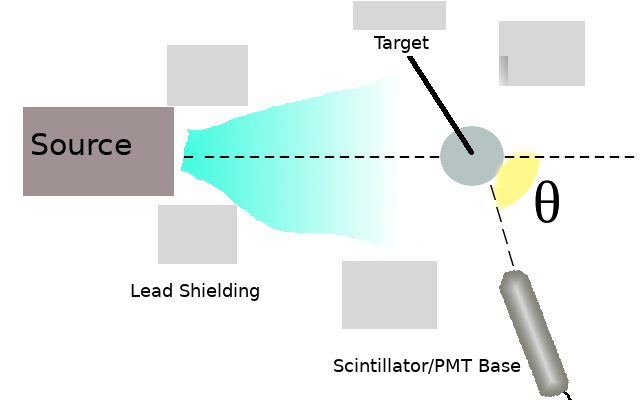

**Fig. 1: Experimental setup**

- The apparatus was calibrated using the Am-241 sample as the source, followed by the Ba-123 sample as the source. Radiation was allowed through a small opening in the shielded lead box and the scintillator was placed within its line of sight, measuring the center of the strongest peak in the energy spectrum observed by the scintillator via the provided spectral analysis software. The following peak vvalues were observed: Cs-137 (weak) - 662.00 keV, Am-241 - 60.32 $\pm$0.41 keV, 83.48 $\pm 1\ldotp 50$keV

- Apparatus setup as shown in Fig. 1, with the strong Cs - 137 sample used as the source.

- Measurements were taken at 15 degree increments, starting from ${135}^{\circ }$and ending at $0^{\circ }$. At each angle, a measurement was taken with the target in place, followed by a measurement without the target in place in order to quantify the noise inherent in the apparatus environment. Each measured spectrum was saved in histogram format as a .txt file, with the naming conventions "THETAhisto.txt" and "THETAnoise.txt", for measurements with and without the target, respectively, at angle THETA. 

**Analysis**

scatter15 = x15Histo.Counts-x15Noise.counts;
energyLevels = .41352222*(1:length(scatter15))

energyLevels =     0.4135    0.8270    1.2406    1.6541    2.0676    2.4811    2.8947    3.3082    3.7217    4.1352    4.5487    4.9623    5.3758    5.7893    6.2028    6.6164    7.0299    7.4434    7.8569    8.2704    8.6840    9.0975    9.5110    9.9245   10.3381   10.7516   11.1651   11.5786   11.9921   12.4057   12.8192   13.2327   13.6462   14.0598   14.4733   14.8868   15.3003   15.7138   16.1274   16.5409   16.9544   17.3679   17.7815   18.1950   18.6085   19.0220   19.4355   19.8491   20.2626   20.6761


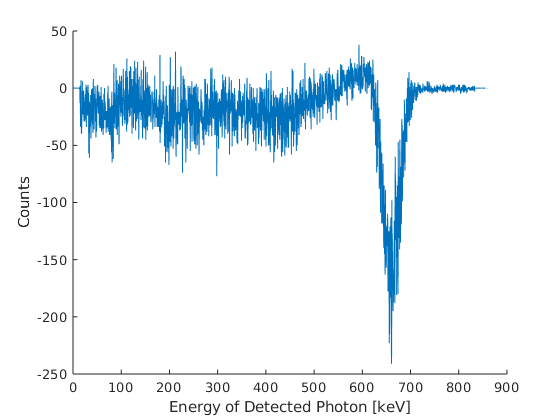

scatter30= x30histo.VarName1 - x30noise.VarName1;
scatter45 = x45histo.VarName1- x45noise.VarName1;
scatter60 = x60histo.VarName1 - x60noise.VarName1;
scatter75 = x75histo.VarName1 - x75noise.VarName1;
scatter90 = x90histo.VarName1 - x90noise.VarName1;
scatter105 = x105histo.VarName1 - x105noise.VarName1;
scatter120 = x120histo.VarName1 - x120noise.VarName1;
scatter135 = x135histo.VarName1 - x135noise.VarName1;

figure
hold on
title("15 Degrees")
plot(energyLevels,scatter15)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

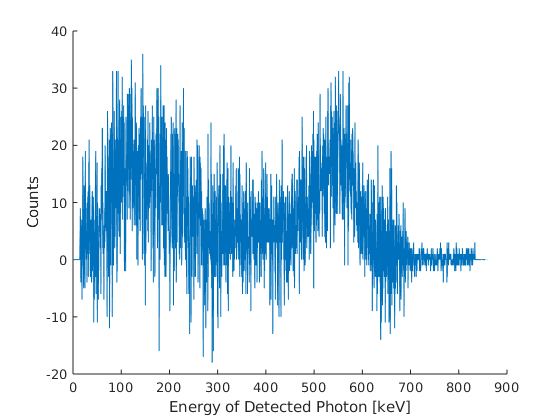


figure
hold on
title("30 Degrees")
plot(energyLevels,scatter30)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

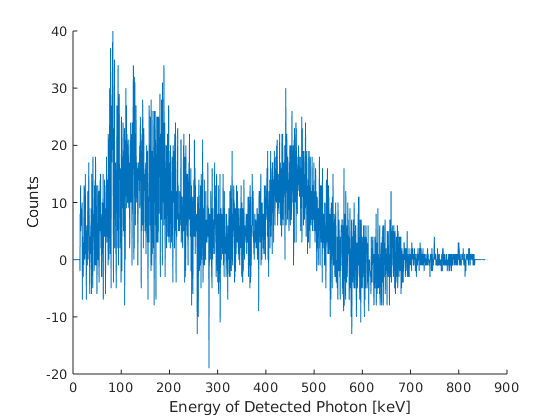


figure
hold on
title("45 Degrees")
plot(energyLevels,scatter45)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

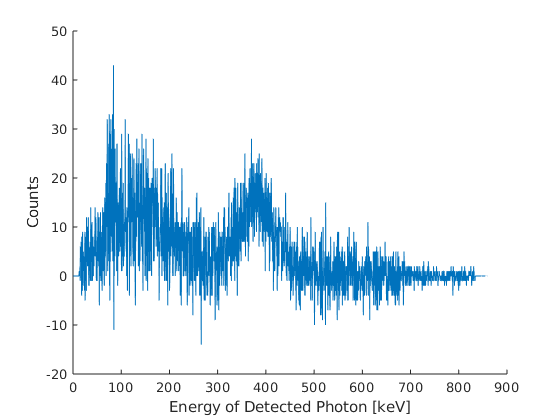


figure
hold on
title("60 Degrees")
plot(energyLevels,scatter60)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

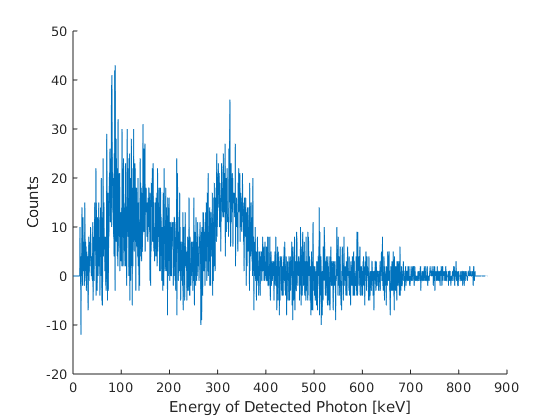


figure
hold on
title("75 Degrees")
plot(energyLevels,scatter75)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

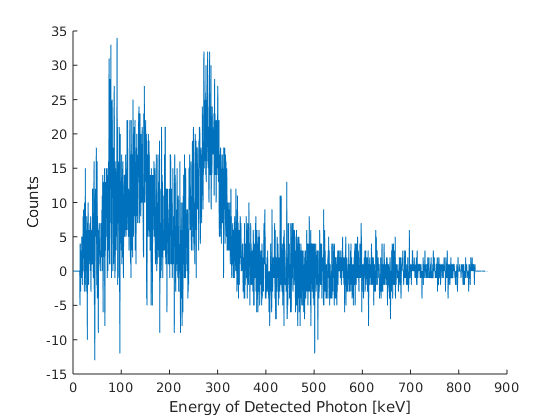


figure
hold on
title("90 Degrees")
plot(energyLevels,scatter90)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

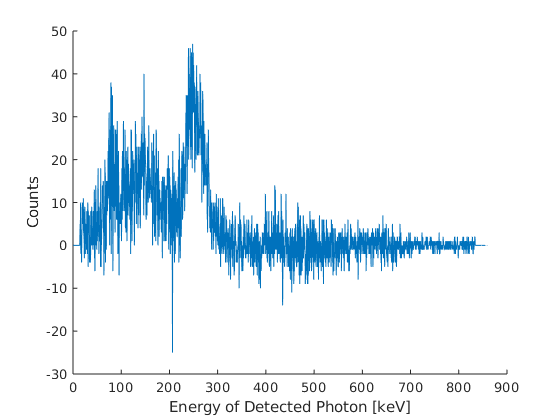


figure
hold on
title("105 Degrees")
plot(energyLevels,scatter105)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

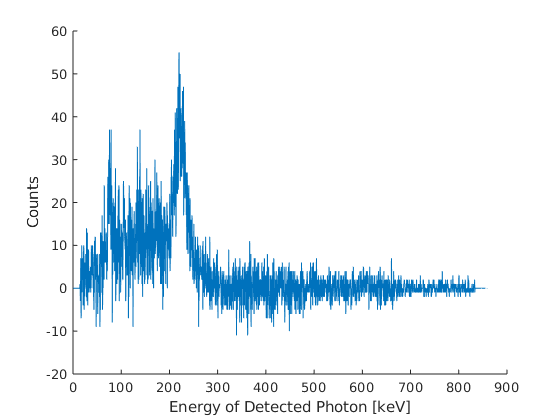


figure
hold on
title("120 Degrees")
plot(energyLevels,scatter120)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

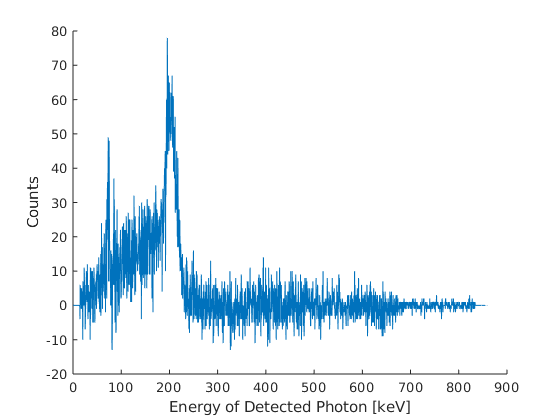


figure
hold on
title("135 Degrees")
plot(energyLevels,scatter135)
xlabel("Energy of Detected Photon [keV]")
ylabel("Counts")
hold off

**Conclusion**